% calculate and plot state value

Animal = 'tph189'; %'s19';
Date = '20230426';
totalTrial = 150;
Key = 'roving10';
gamma = 0.9; % discount factor
position_range = [657 672]; % [630-647]
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022'; % Linux
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation'  filesep Date '_' Animal '_' Key]; % Linux
load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
data = behavior_sequence_fps;
output_dir = '/home/naohiro/Desktop/Doya_rotation/analysis/output/behavior/2304_single/';

% bin the state and action to calculate state value and action value
behavior_sequence_discretized = cell(1,length(data));
for i_trial = 1:length(data)
    % bin lever position (657-672 -> 5-1) %(630-647 -> 6-1)
    position_temp = data{i_trial}(:,3);
    position_discrete = 6 - min(max(floor((position_temp - (position_range(1)-6))/4),1),5);
%     position_discrete = 7 - min(max(floor((position_temp - 623)/4),1),6);
%     position_discrete = zeros(length(position_temp));
%     for j_time = 1:length(position_temp)
%         if position_temp(j_time) <= 
    % bin applied force (0-0.7 -> 0-7)
    force_temp = data{i_trial}(:,4);
    force_discrete = min(max(floor(force_temp/0.1),0),7);
%     force_discrete = min(max(idivide(force_temp,0.1,'floor'),0),7);
    behavior_sequence_discretized{i_trial} = cat(2,cat(2,data{i_trial},position_discrete),force_discrete);
end

% analyze first 50 of last 50 trials as before and after adaptation
behavior_adapt = cell(2,50);
behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
behavior_adapt(2,:) = behavior_sequence_discretized(length(data)-49:length(data)); % behavior_after_adapt

% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
state_value = cell(2,10);
for k = 1:2
    for i_trial = 1:50
        % resistance for each trial
        if behavior_adapt{k,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_adapt{k,i_trial}(:,5)) == 1
            rewarded_trial = length(behavior_adapt{k,i_trial});
        else 
            rewarded_trial = 0;
        end
        % add state_value of each step
        for j_step = 1:size(behavior_adapt{k,i_trial},1)
            state_temp = (resistance_trial-1)*5+behavior_adapt{k,i_trial}(j_step,7);
            if rewarded_trial >= 1
                state_value_temp = gamma.^(rewarded_trial-j_step);
            else
                state_value_temp = 0;
            end
            state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
        end
    end
end

state_value_average = zeros(2,10);
for i = 1:10
    state_value_average(1,i) = mean(state_value{1,i});
    state_value_average(2,i) = mean(state_value{2,i});
end
% rewarded after how many steps or not

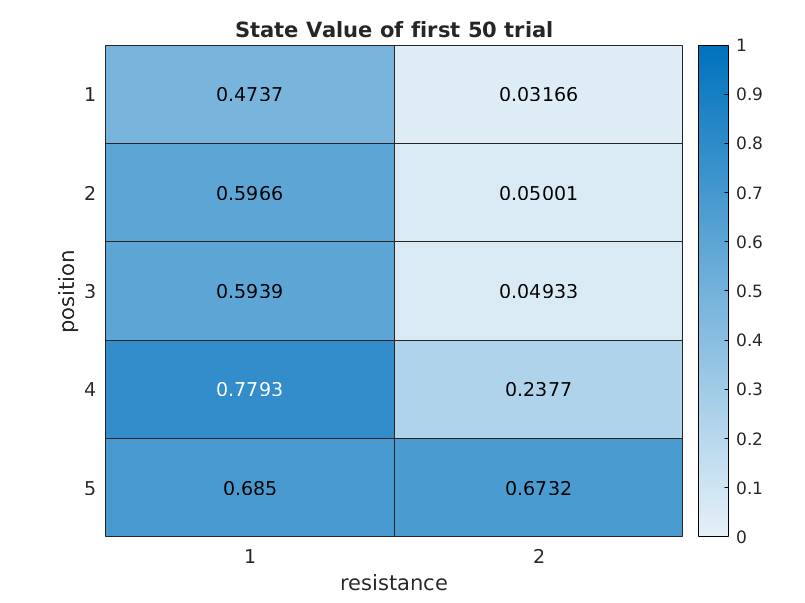

% plot state value
state_value_average_reshape = reshape(state_value_average(1,:),[5,2]);
heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of first 50 trial','XLabel','resistance','YLabel','position')
filename = [output_dir Date '_' Animal, '_State_Value_first50.png'];
saveas(gcf,filename);

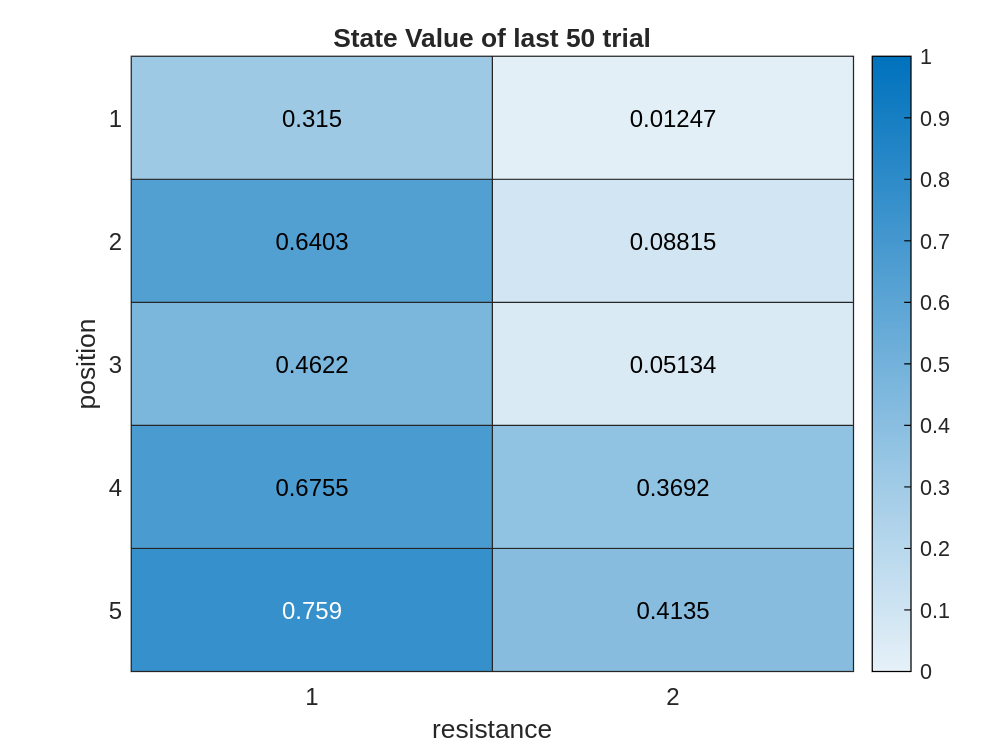

state_value_average_reshape = reshape(state_value_average(2,:),[5,2]);
heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of last 50 trial','XLabel','resistance','YLabel','position')
filename = [output_dir Date '_' Animal, '_State_Value_last50.png'];
saveas(gcf,filename);

% analyze by binned 20 trials
num_bins = 6; % 6 % number of bins
num_width = 25; % 20
behavior_adapt = cell(num_bins,num_width);
for i = 1:num_bins
%     if i == 6
%         behavior_adapt(6,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-19:length(behavior_sequence_processed));
%     else
        behavior_adapt(i,:) = behavior_sequence_discretized((i-1)*num_width+1:i*num_width);
%     end
end
% behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% behavior_adapt(2,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-49:length(behavior_sequence_processed)); % behavior_after_adapt

% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
state_value = cell(num_bins,10);
for k = 1:num_bins
    for i_trial = 1:num_width
        % resistance for each trial
        if behavior_adapt{k,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_adapt{k,i_trial}(:,5)) == 1
            rewarded_trial = length(behavior_adapt{k,i_trial});
        else 
            rewarded_trial = 0;
        end
        % add state_value of each step
        for j_step = 1:size(behavior_adapt{k,i_trial},1)
            state_temp = (resistance_trial-1)*5+behavior_adapt{k,i_trial}(j_step,7);
            if rewarded_trial >= 1
                state_value_temp = gamma.^(rewarded_trial-j_step);
            else
                state_value_temp = 0;
            end
            state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
        end
    end
end

state_value_average = zeros(num_bins,10);
for k = 1:num_bins
    for i = 1:10
        state_value_average(k,i) = mean(state_value{k,i});
%     state_value_average(2,i) = mean(state_value{2,i});
    end
end
% rewarded after how many steps or not

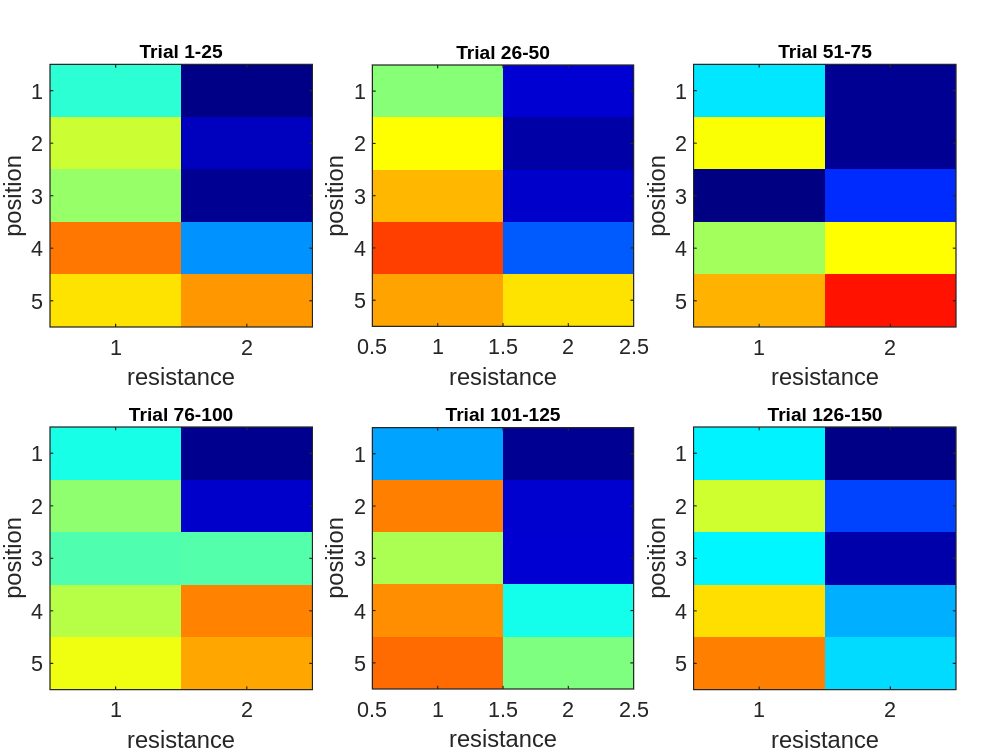

% plot state value
% addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);
addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
for i = 1:num_bins
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape)
    subaxis(2,3,i, 'Spacing', 0.02, 'Padding', 0.02, 'Margin', 0.03);
%     clims = [-3 10]; % use clims specified by the previous cell
%     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
    state_value_average_reshape = reshape(state_value_average(i,:),[5,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
    imagesc(state_value_average_reshape,[0 1]);
    colormap jet;
    axis square;
%     axis off;
    title(['Trial ' num2str(1+(i-1)*num_width) '-' num2str(i*num_width)], 'FontSize',8);
    xlabel('resistance');
    ylabel('position');
end
filename = [output_dir Date '_' Animal, '_State_Value_25bin.png'];
saveas(gcf,filename);

% analyze by binned 20 trials
num_bins = 12; % 12; % 6 % number of bins
num_width = 12; % 20
behavior_adapt = cell(num_bins,num_width);
for i = 1:num_bins
%     if i == 6
%         behavior_adapt(6,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-19:length(behavior_sequence_processed));
%     else
    if rem(i,2)==0
        behavior_adapt(i,:) = behavior_sequence_discretized((i/2)*25-num_width+1:(i/2)*25);
    else 
        behavior_adapt(i,:) = behavior_sequence_discretized(((i-1)/2)*25+1:((i-1)/2)*25+num_width);        
    end
end
% behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% behavior_adapt(2,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-49:length(behavior_sequence_processed)); % behavior_after_adapt

% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
state_value = cell(num_bins,10);
for k = 1:num_bins
    for i_trial = 1:num_width
        % resistance for each trial
        if behavior_adapt{k,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_adapt{k,i_trial}(:,5)) == 1
            rewarded_trial = length(behavior_adapt{k,i_trial});
        else 
            rewarded_trial = 0;
        end
        % add state_value of each step
        for j_step = 1:size(behavior_adapt{k,i_trial},1)
            state_temp = (resistance_trial-1)*5+behavior_adapt{k,i_trial}(j_step,7);
            if rewarded_trial >= 1
                state_value_temp = gamma.^(rewarded_trial-j_step);
            else
                state_value_temp = 0;
            end
            state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
        end
    end
end

state_value_average = zeros(num_bins,10);
for k = 1:num_bins
    for i = 1:10
        state_value_average(k,i) = mean(state_value{k,i});
%     state_value_average(2,i) = mean(state_value{2,i});
    end
end
% rewarded after how many steps or not

% plot state value
addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);

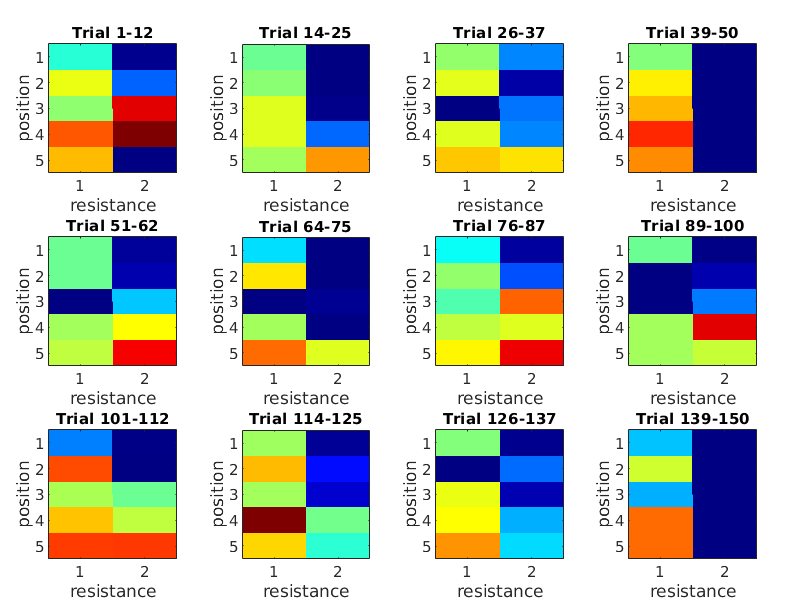

for i = 1:num_bins
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape)
    subaxis(3,4,i, 'Spacing', 0.02, 'Padding', 0.03, 'Margin', 0.03);
%     clims = [-3 10]; % use clims specified by the previous cell
%     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
    state_value_average_reshape = reshape(state_value_average(i,:),[5,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
    imagesc(state_value_average_reshape,[0 1]);
    colormap jet;
    axis square;
%     axis off;
    if rem(i,2)==0
        title(['Trial ' num2str((i/2)*25-num_width+1) '-' num2str((i/2)*25)], 'FontSize',8);
    else 
%         behavior_adapt(i,:) = behavior_sequence_discretized(((i-1)/2)*25+1:((i-1)/2)*25+num_width); 
        title(['Trial ' num2str(((i-1)/2)*25+1) '-' num2str(((i-1)/2)*25+num_width)], 'FontSize',8);
    end
%     title(['Trial ' num2str(1+(i-1)*num_width) '-' num2str(i*num_width)], 'FontSize',8);
    xlabel('resistance');
    ylabel('position');
end
filename = [output_dir Date '_' Animal, '_State_Value_12bin.png'];
saveas(gcf,filename);

% analyze by linearly increase the contribution of past trials
effective_trials = 50; % maximam trial which affect current state or action value
% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
trial_num = length(data);
state_value = cell(trial_num,10);
for i_trial = 1:trial_num
     % resistance for each trial
    if behavior_sequence_discretized{i_trial}(1,2) == 8
        resistance_trial = 1;
    else 
        resistance_trial = 2;
    end
    % rewarded step (end of trial) or not (0)
    if max(behavior_sequence_discretized{i_trial}(:,5)) == 1
        rewarded_trial = size(behavior_sequence_discretized{i_trial},1);
    else 
        rewarded_trial = 0;
    end
    % calculate state_value of each step
    for j_step = 1:size(behavior_sequence_discretized{i_trial},1)
        state_temp = (resistance_trial-1)*5+behavior_sequence_discretized{i_trial}(j_step,7);
        if rewarded_trial >= 1
            state_value_temp = gamma.^(rewarded_trial-j_step);
        else
            state_value_temp = 0;
        end
        state_value{i_trial,state_temp} = [state_value{i_trial,state_temp} state_value_temp];
    end   
end

state_value_average = zeros(trial_num,10);
for i_trial = 1:trial_num
    for i = 1:10
        state_value_average(i_trial,i) = mean(state_value{i_trial,i});
%     state_value_average(2,i) = mean(state_value{2,i});
    end
end
% rewarded after how many steps or not

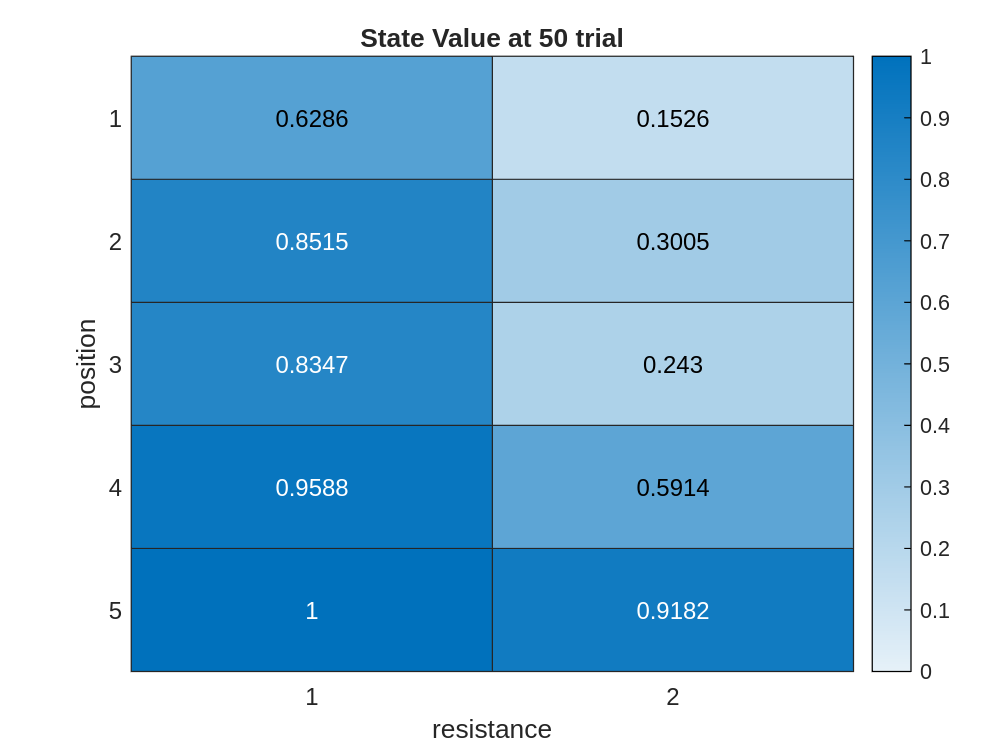

% plot state value at trial50 
clf('reset')
state_value_weighted_average = zeros(1,10);
% for i_trial = 1:effective_trials
%     for i = 1:12
%         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%     end
% end
for i = 1:10
    sum_weights = 0;
    for i_trial = 1:effective_trials
        if ~isnan(state_value_average(50-effective_trials+i_trial,i))
            state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
            sum_weights = sum_weights + i_trial;
        end
    end
    state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

state_value_weighted_average_reshape = reshape(state_value_weighted_average,[5,2]);
heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 50 trial','XLabel','resistance','YLabel','position')
filename = [output_dir Date '_' Animal, '_State_Value_at50.png'];
saveas(gcf,filename);

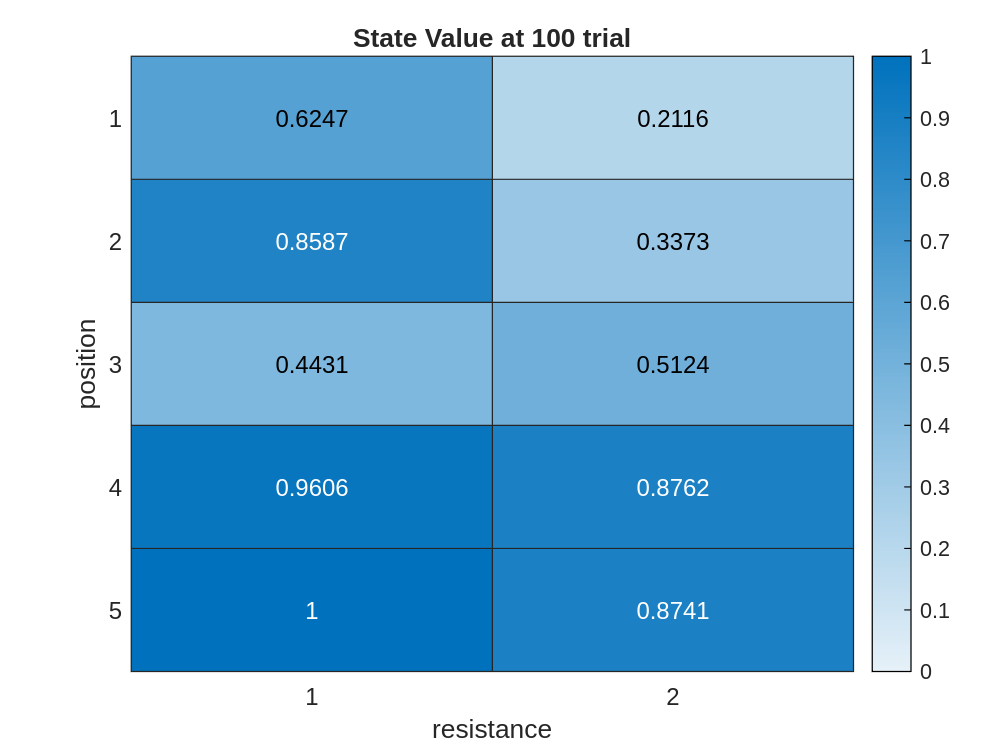

% plot state value at trial100 
% clf('reset')
state_value_weighted_average = zeros(1,10);
% for i_trial = 1:effective_trials
%     for i = 1:12
%         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%     end
% end
for i = 1:10
    sum_weights = 0;
    for i_trial = 1:effective_trials
        if ~isnan(state_value_average(100-effective_trials+i_trial,i))
            state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(100-effective_trials+i_trial,i);
            sum_weights = sum_weights + i_trial;
        end
    end
    state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

state_value_weighted_average_reshape = reshape(state_value_weighted_average,[5,2]);
heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 100 trial','XLabel','resistance','YLabel','position')
filename = [output_dir Date '_' Animal, '_State_Value_at100.png'];
saveas(gcf,filename);

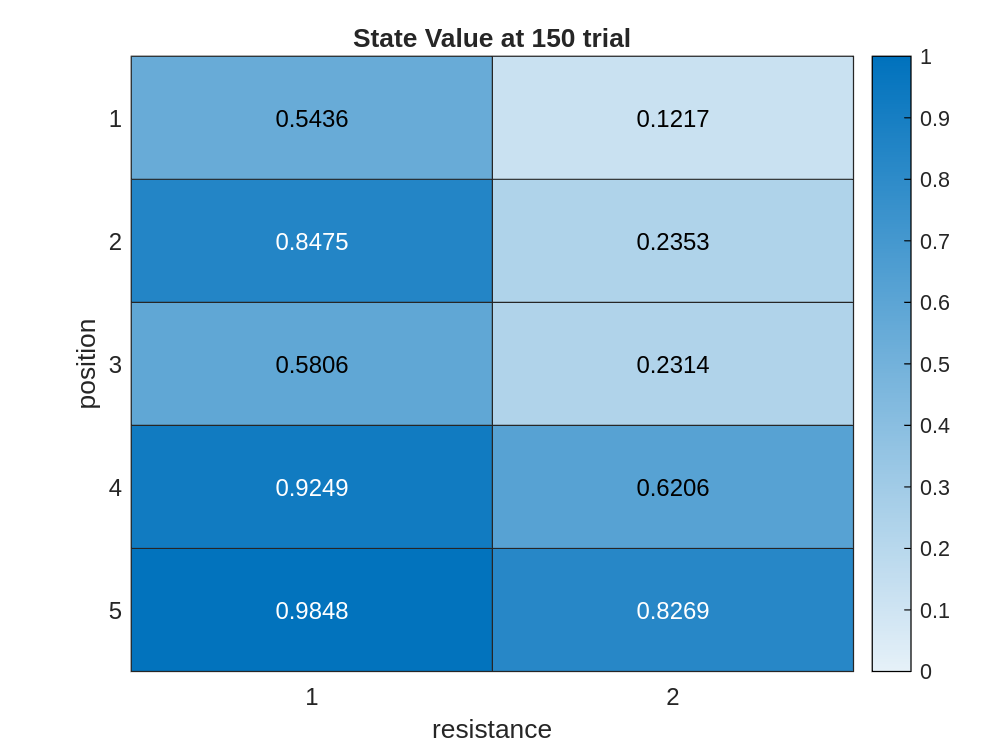

% plot state value at trial150 
% clf('reset')
state_value_weighted_average = zeros(1,10);
% for i_trial = 1:effective_trials
%     for i = 1:12
%         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%     end
% end
for i = 1:10
    sum_weights = 0;
    for i_trial = 1:effective_trials
        if ~isnan(state_value_average(150-effective_trials+i_trial,i))
            state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(150-effective_trials+i_trial,i);
            sum_weights = sum_weights + i_trial;
        end
    end
    state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

state_value_weighted_average_reshape = reshape(state_value_weighted_average,[5,2]);
heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 150 trial','XLabel','resistance','YLabel','position')
filename = [output_dir Date '_' Animal, '_State_Value_at150.png'];
saveas(gcf,filename);

gamma = 0.9 % discount factor

gamma = 0.9000

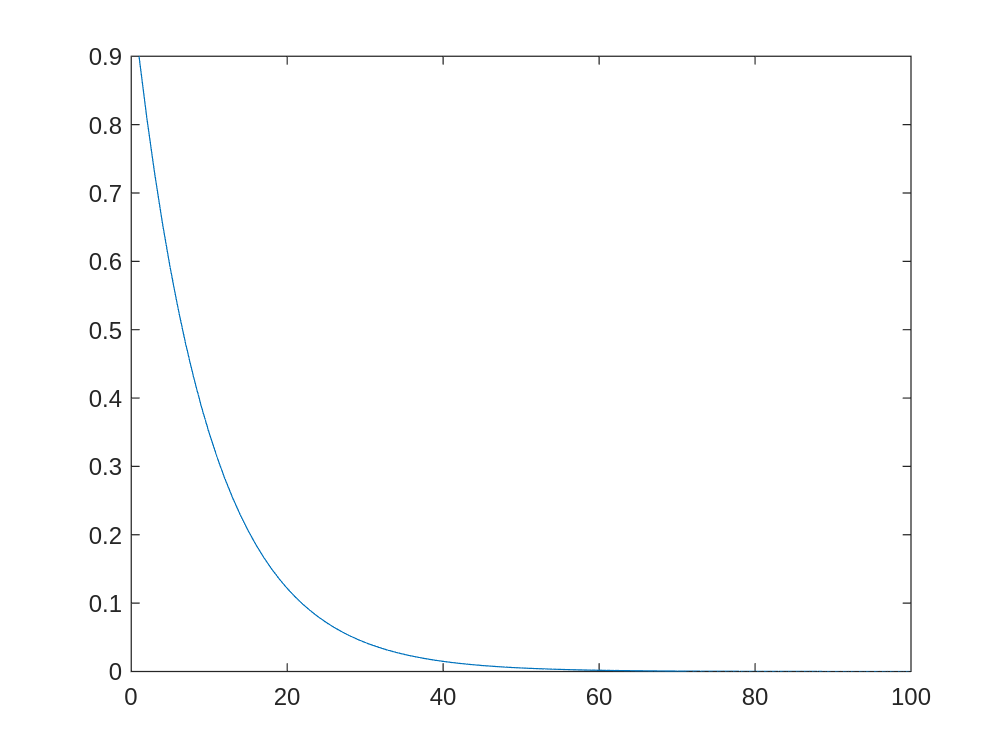

x = 1:100;
y = gamma.^x;
plot(y)

clf('reset')
steps = 0;
data_lengths = zeros(length(data),1);
for i_trial = 1:length(data)
    steps = steps + length(data{i_trial});
    data_lengths(i_trial) = length(data{i_trial});
end
steps = steps/length(data)

steps = 32.7467

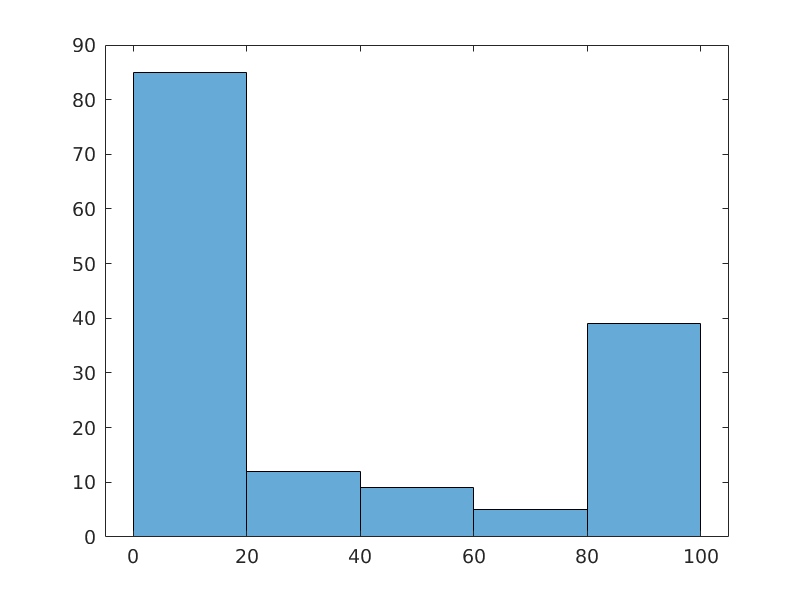

histogram(data_lengths); %, 'BinLimits',[0 1])

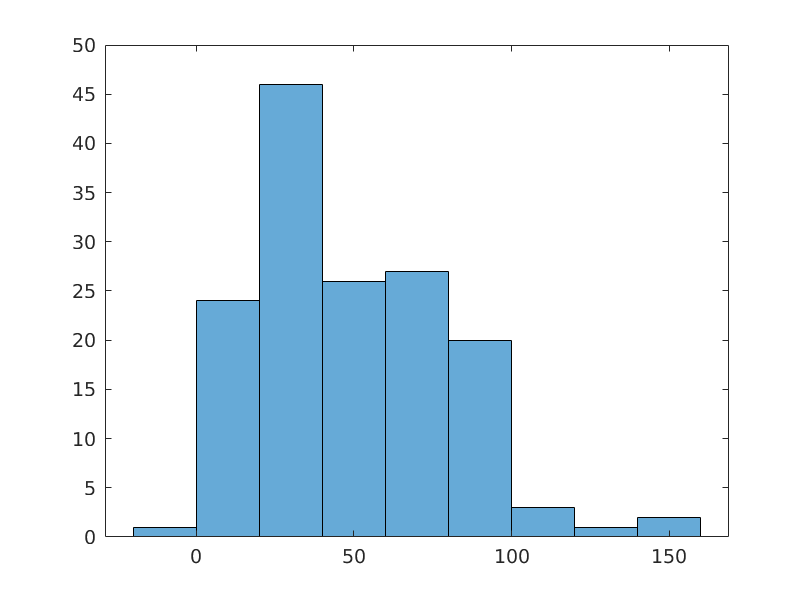

clf('reset')
max_forces = zeros(1,length(data));
for i = 1:length(data)
    max_forces(i) = max(data{i}(:,4));
end
histogram(max_forces);%, 'BinLimits',[0 1])

resistance_list = zeros(1,length(data));
for i = 1:length(data)
    resistance_list(i) = data{i}(1,2);
end

res_heavy_num = sum(resistance_list~=8);
res_light_num = sum(resistance_list==8);
max_forces_heavy = zeros(1,length(res_heavy_num));
max_forces_light = zeros(1,length(res_light_num));
rewarded_heavy = zeros(1,length(res_heavy_num));
rewarded_light = zeros(1,length(res_light_num));
h = 0;l = 0;
for i = 1:length(data)
    if resistance_list(i) ~= 8
        h = h + 1;
        max_forces_heavy(h) = max(data{i}(:,4));
        rewarded_heavy(h) = max(data{i}(:,5));
    else
        l = l + 1;
        max_forces_light(l) = max(data{i}(:,4));
        rewarded_light(l) = max(data{i}(:,5));
    end
end

% add function to output resistance and max force of each trial
Trials = 1:length(data);
max_forces = zeros(1, length(data));
for i = 1:length(data)
    max_forces(i) = max(data{i}(:,4));
end
CSVFilename = [data_folder filesep Animal '_resistance_force_' Date '_' Key];
Output = [transpose(Trials) transpose(resistance_list) transpose(max_forces)]

Output =     1.0000    8.0000   63.6730
    2.0000    8.0000   90.2555
    3.0000    8.0000   80.5339
    4.0000    8.0000   14.6093
    5.0000    8.0000   26.8915
    6.0000    8.0000   44.9893
    7.0000    8.0000   21.2929
    8.0000    8.0000   70.9642
    9.0000    8.0000   13.3507
   10.0000    8.0000   42.2551


csvwrite(CSVFilename,Output);

% add function to output resistance, force (posterior) and observation
% (pos(t)-pos(t-1))/force(t-1)

Output_tri = []; Output_res = []; Output_pos = []; Output_for = [];
for i = 1:length(data)
    Output_tri = [Output_tri; data{i}(:,1)];
    Output_res = [Output_res; data{i}(:,2)];
    Output_pos = [Output_pos; data{i}(:,3)];
    Output_for = [Output_for; data{i}(:,4)];
end
% Trials = 1:length(data);
% max_forces = zeros(1, length(data));
% for i = 1:length(data)
%     max_forces(i) = max(data{i}(:,4));
% end
CSVFilename = [data_folder filesep Animal '_resistance_force_pos_' Date '_' Key];
Output2 = [Output_tri Output_res Output_pos Output_for]

Output2 =     1.0000    8.0000  668.5000   63.6730
    1.0000    8.0000  654.0000   36.7867
    2.0000    8.0000  669.3333   90.2555
    2.0000    8.0000  654.0000   56.8375
    3.0000    8.0000  672.3333   80.5339
    3.0000    8.0000  660.5000   39.5209
    4.0000    8.0000  672.7500   -0.5807
    4.0000    8.0000  672.8571   -0.7109
    4.0000    8.0000  673.0000    0.7358
    4.0000    8.0000  672.8750    0.5586


csvwrite(CSVFilename,Output2);

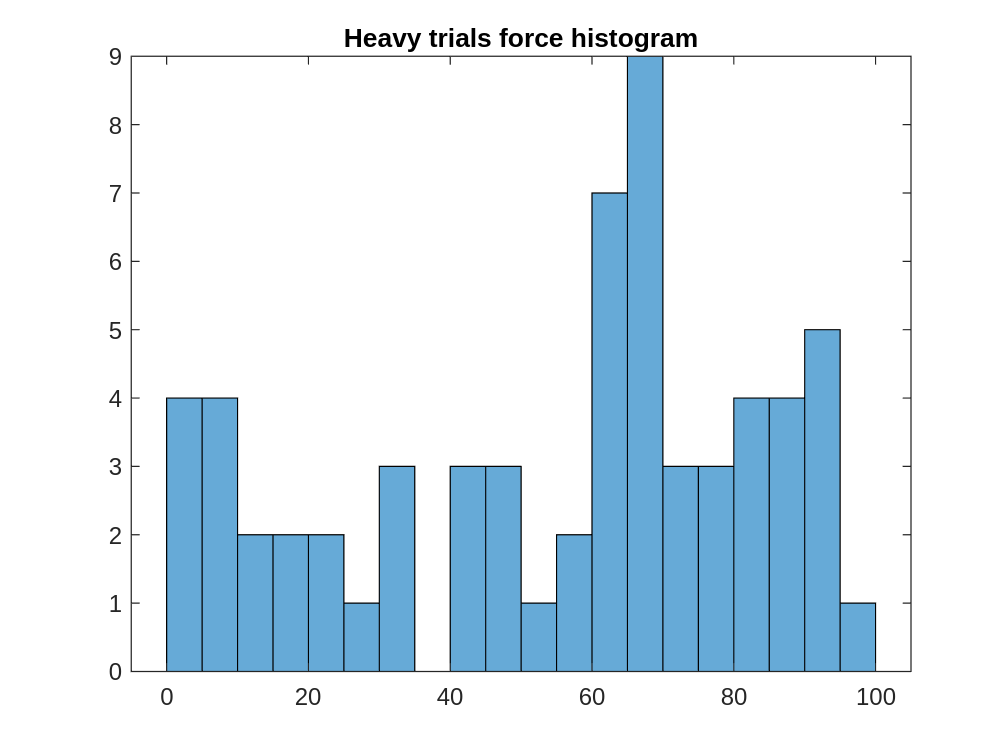

clf('reset')
edges = linspace(0, 100, 21);
histogram(max_forces_heavy, 'BinEdges',edges);%, 'BinLimits',[0 1])
title('Heavy trials force histogram');

mean(max_forces_heavy)

ans = 59.7722

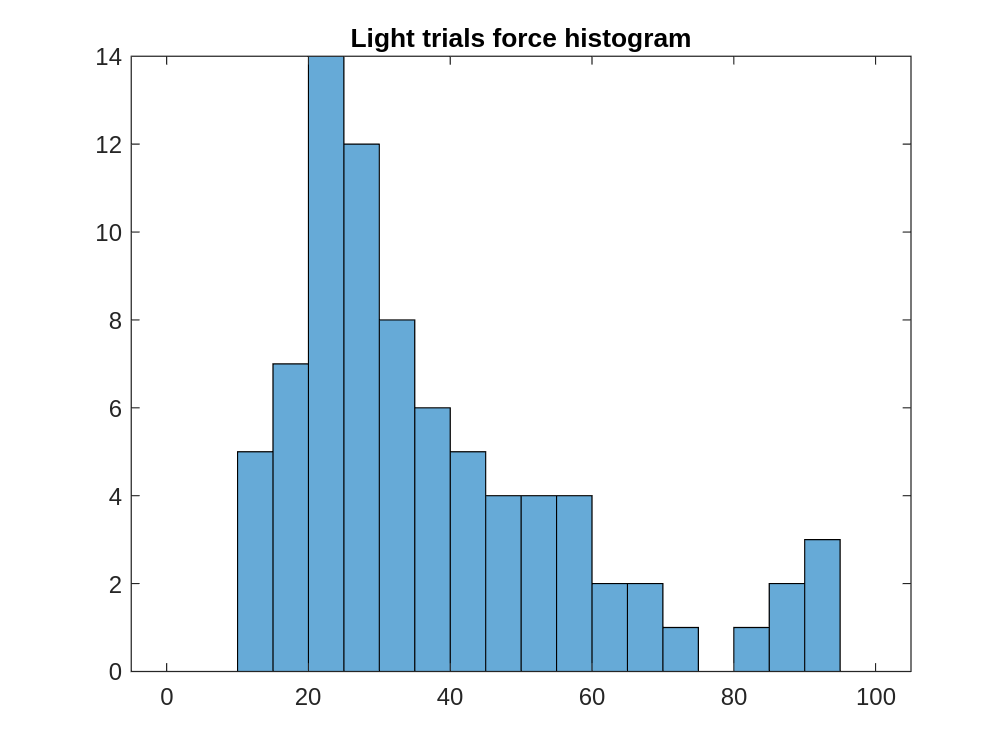

clf('reset')
edges = linspace(0, 100, 21);
histogram(max_forces_light, 'BinEdges',edges);%, 'BinLimits',[0 1])
title('Light trials force histogram');

mean(max_forces_light)

ans = 37.7742

success_rate_heavy = sum(rewarded_heavy)/length(rewarded_heavy)

success_rate_heavy = 0.4429

success_rate_light = sum(rewarded_light)/length(rewarded_light)

success_rate_light = 0.9875

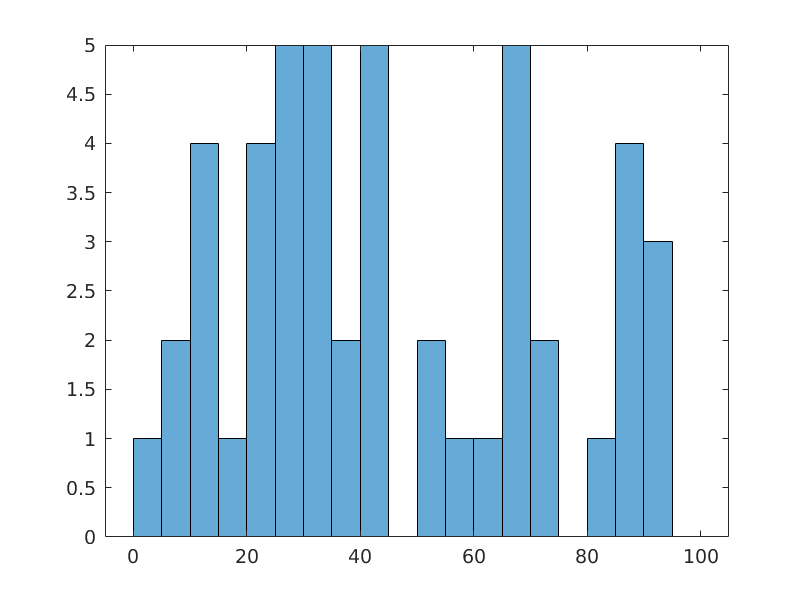

clf('reset')
max_forces = zeros(1,50);
for i = 1:50
    max_forces(i) = max(data{i}(:,4));
end
edges = linspace(0, 100, 21);
histogram(max_forces, 'BinEdges',edges);%, 'BinLimits',[0 1])

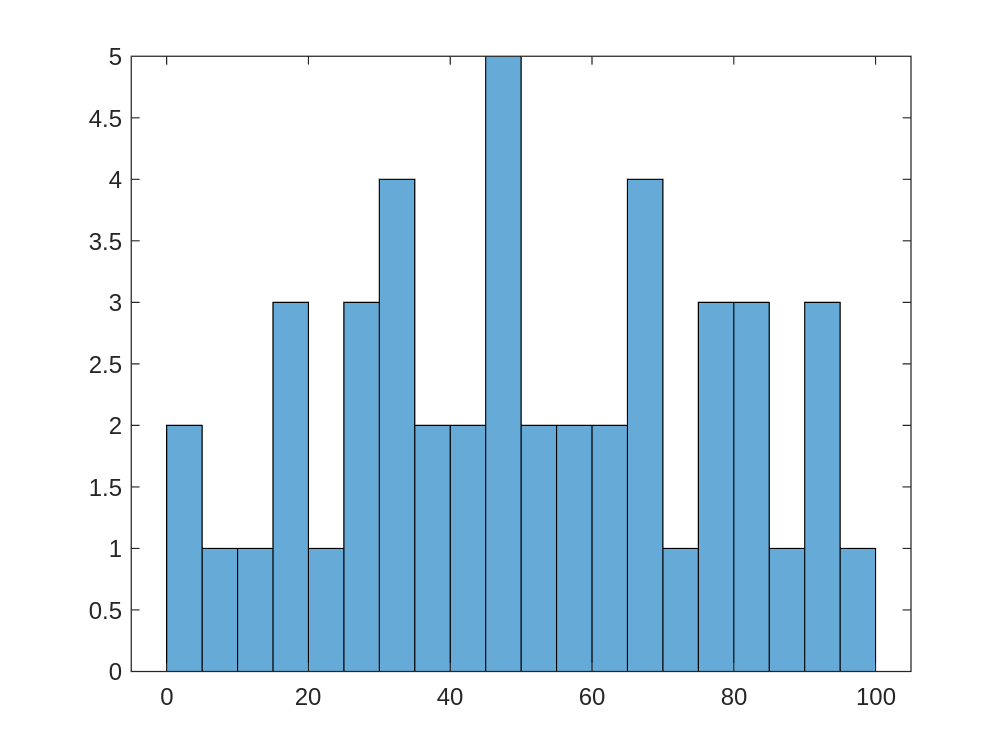

clf('reset')
max_forces = zeros(1,50);
for i = 1:50
    max_forces(i) = max(data{50+i}(:,4));
end
edges = linspace(0, 100, 21);
histogram(max_forces, 'BinEdges',edges);%, 'BinLimits',[0 1])

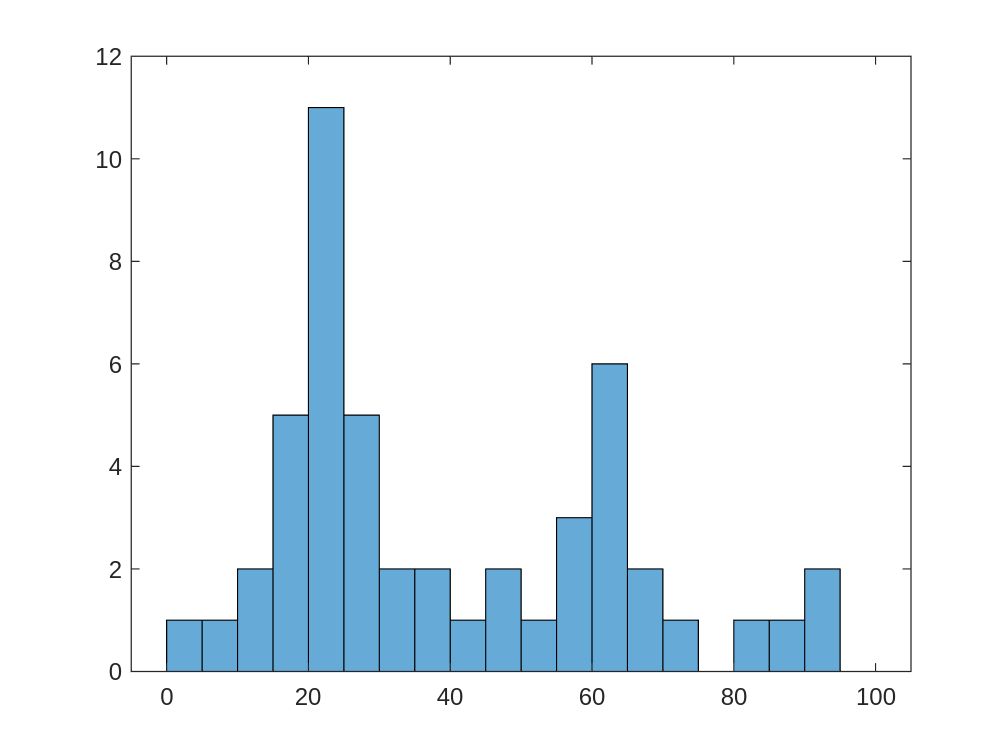

clf('reset')
max_forces = zeros(1,50);
for i = 1:50
    max_forces(i) = max(data{100+i}(:,4));
end
edges = linspace(0, 100, 21);
histogram(max_forces, 'BinEdges',edges);%, 'BinLimits',[0 1])